rL = 0.02;                 % Resistance (Ohms)
RL = 10;                   % Load resistance (Ohms)
L = 1e-3;                  % Inductance (H)
CO = 40e-6;                % Capacitance (F)
Vi = 10;                   % Input voltage (V)
fs = 5e3;                  % Switching frequency (Hz)
Tp = 1/fs;                 % Switching period
dt = 4e-6;                 % Time step
k = [0.3 0.7]              % Duty Cycle 

k =     0.3000    0.7000


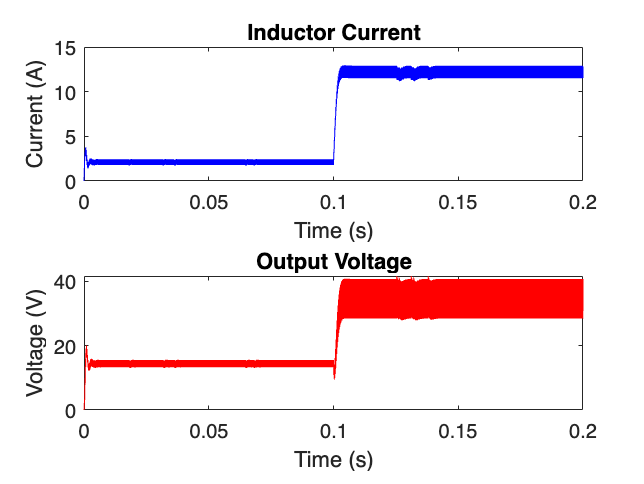

isave = [];
vsave = [];
sim_time = [];
Vo = 0;
iL = 0;
B = [1/L; 0];
for t = 0:dt:(1000*Tp)
    t_instant = mod(t, Tp);

     if t<0.1             % Condition for fetching the duty cycle 
            i=1;
        else
            i=2;
        end 
     if t_instant < (k(i) * Tp)
        D = 1;            % switch is closed (on)
     else
         D = 0;           % switch is open (off)
     end
     A = [(-rL/L) -(1-D)/L; (1-D)/CO -1/(RL*CO)];
     if t == 0
        x = [iL; Vo];
     else                 % Runge Kutta method implementing 
        k1 = dt * (A * x + B * Vi);
        k2 = dt * (A * (x + 0.5 * k1) + B * Vi);
        k3 = dt * (A * (x + 0.5 * k2) + B * Vi);
        k4 = dt * (A * (x + k3) + B * Vi);
        x = x + (1/6) * (k1 + 2 * k2 + 2 * k3 + k4);
     end
    iL = x(1,1);
    Vo = x(2,1);
    isave = [isave, x(1,1)];
    vsave = [vsave, x(2,1)];
    sim_time = [sim_time, t];
end
figure;
subplot(2, 1, 1);
plot(sim_time, isave, 'b');
xlabel('Time (s)');
ylabel('Current (A)');
title('Inductor Current');
subplot(2, 1, 2);  % Plot the capacitor voltage against time
plot(sim_time, vsave, 'r');
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Output Voltage');